alpha=1+mod(217,3);

## Problem 1

%Specify the parameters
sampling_rate=720;
Rp=-(alpha);
Wp=10/(sampling_rate/2);   %Edge frequencies are always normalized wrt sampling rate
Rs=40;
Ws=20/(sampling_rate/2);

%Find the butterworth filter order
[n,Wn]=buttord(Wp, Ws, Rp, Rs);

%Design the butterworth filter
[b,a]=butter(n, Wn,"low");

%Generate the transfer function
syms z
numer=poly2sym(b, z);
denom=poly2sym(a, z);
H=numer/denom

$$H = \frac{\frac{2064068798413583\,z^{8}}{77371252455336267181195264}+\frac{2064068798413583\,z^{7}}{9671406556917033397649408}+\frac{1806060198611885\,z^{6}}{2417851639229258349412352}+\frac{1806060198611885\,z^{5}}{1208925819614629174706176}+\frac{4515150496529713\,z^{4}}{2417851639229258349412352}+\frac{1806060198611885\,z^{3}}{1208925819614629174706176}+\frac{1806060198611885\,z^{2}}{2417851639229258349412352}+\frac{2064068798413583\,z}{9671406556917033397649408}+\frac{2064068798413583}{77371252455336267181195264}}{z^{8}-\frac{8439811641607913\,z^{7}}{1125899906842624}+\frac{3461935865922655\,z^{6}}{140737488355328}-\frac{811943418705467\,z^{5}}{17592186044416}+\frac{952696763352943\,z^{4}}{17592186044416}-\frac{715829680368983\,z^{3}}{17592186044416}+\frac{2690760566894089\,z^{2}}{140737488355328}-\frac{2891393384261979\,z}{562949953421312}+\frac{2720050138483955}{4503599627370496}}$$


%Find the poles of the filter
[z,p,k]=tf2zpk(b,a);
p

p =    0.9765 + 0.0945i
   0.9765 - 0.0945i
   0.9437 + 0.0774i
   0.9437 - 0.0774i
   0.9201 + 0.0504i
   0.9201 - 0.0504i
   0.9078 + 0.0175i
   0.9078 - 0.0175i


if all(abs(p) < 1)
    fprintf('The system is stable.\n');
else
    fprintf('The system is unstable.\n');
end

The system is stable.


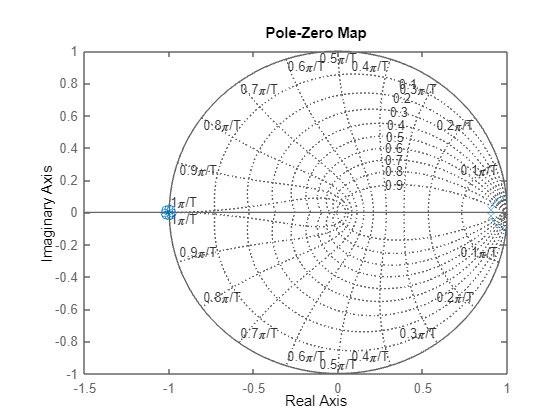


%Plot the pole zero plot
sys=tf(b,a,1/sampling_rate);
pzplot(sys)
grid on;

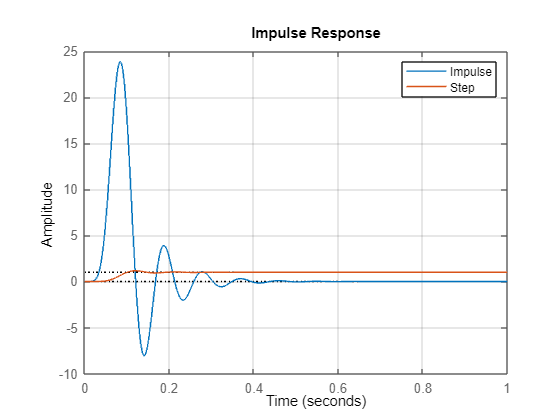


%Plot the impulse and step response
impulse(sys, 1);
hold on;
step(sys, 1);
hold off;
grid on;
legend("Impulse","Step");


%Plot the bode plot
freq_spec=linspace(0,50,1e3);
bode(sys, 2*pi*freq_spec);

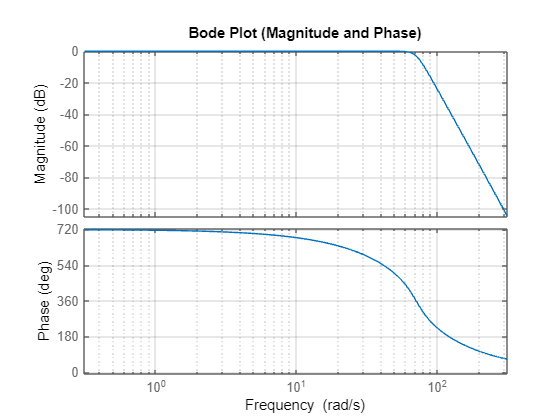

title("Bode Plot (Magnitude and Phase)");
grid on;

## Problem 2

%Import the data
ECG_data=load("ECG_Data.txt");

Error using load
'ECG_Data.txt'
is not
found
in the
current
folder
or on
the
MATLAB
path,
but
exists
in:
    F:\DSP

Change
the
MATLAB
current
folder
or add
its
folder
to the
MATLAB
path.


%Apply the butterworth filter
fitlered_ecg=filtfilt(b,a,ECG_data);

% Create time vector for plotting
time=(0:length(ECG_data)-1)/sampling_rate;

%Plot the original and filtered signals
subplot(2,1,1)
plot(time, ECG_data);
title("Original ECG");
xlabel("Time(s)");
ylabel("AMplitude");
grid on;
subplot(2,1,2);
plot(time, fitlered_ecg);
title("Filtered ECG Signal");
xlabel("Time(s)");
ylabel("Amplitude");
grid on;

## Problem 3

%Specify the parameters
[y, Fs]=audioread("instru3.wav");
window_size=1024;
overlap=window_size/2;

%Calculate the spectrogram
[S,F,T]=spectrogram(y, hamming(window_size), overlap, [], Fs);

%Design the butterworth band pass filter
f_cuttoff= 1500;
bandwidth=100;
[n, Wn]=nuttord(bandwidth/(Fs/2), f_cuttoff/(Fs/2), Rp, Rs);
[b,a]=butter(1, [(f_cuttoff- bandwidth/2) (f_cuttoff+bandwidth/2)]/(Fs/2), "bandpass");

%Apply the filter to the signal
filtered_signal=filter(b,a,y);
[S_filtered, ~,~]=spectrogram(filtered_signal, hamming(window_size), overlap, [], Fs);

%Plot both the original and filtered signal
subplot(2,1,1)
imagesc(T,F, 10*log10(abs(S)))
axis xy
colormap jet;
title("Original Spectrogram")
xlabel("Time(s)");
ylabel("Frequency(Hz)");
colorbar;

subplot(2,1,2)
imagesc(T,F,10*log10(abs(S_filtered)))
axis xy
colormap jet;
title("Filtered Spectrogram");
xlabel("Time(s)");
ylabel("Frequency(Hz)");
colorbar;

%Save the file in WAV format
audiowrite("filtered_output.wav", filtered_signal, Fs);

%Listen to the file
%sound(y, Fs)
sound(filtered_signal, Fs)

## Problem 4

%Design the Chebyshev filter
[N,W]=cheb1ord(Wp, Ws, Rp, Rs);
[zero, pole]=cheby1(N, -Rp, Wp);
fprintf("Butterworth Order: %d", n);
fprintf("Chebyshev Order: %d", N);

%Plot the bode plots of both the figures
bode(sys);
hold on;
bode(tf(zero, pole, 1/sampling_rate));
hold off;
grid on;
title("Bode Comparison of the two filters");
legend("Butterworth", "Chebyshev");

%Plot the impulse and step response of the two filters
subplot(2,1,1);
impulse(sys, 1);
hold on;
impulse(tf(zero, pole, 1/sampling_rate), 1);
hold off;
grid on;
legend("Butterworth","Chebyshev");

subplot(2,1,2);
step(sys, 1);
hold on;
step(tf(zero, pole, 1/sampling_rate), 1);
hold off;
grid on;
legend("Butterworth", "Chebyshev");
